ax = axes('XLim',[-15 15],'YLim',[-15 15],'ZLim',[-5 25]);
view(3)

[x,y,z] = ellipsoid(0,5,0,2,2,4,20);

hold on

h(1)=surf(x,y,z,'FaceColor','yellow')

h =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: [1 1 0]
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [21×21 double]
           YData: [21×21 double]
           ZData: [21×21 double]
           CData: [21×21 double]

  显示 所有属性


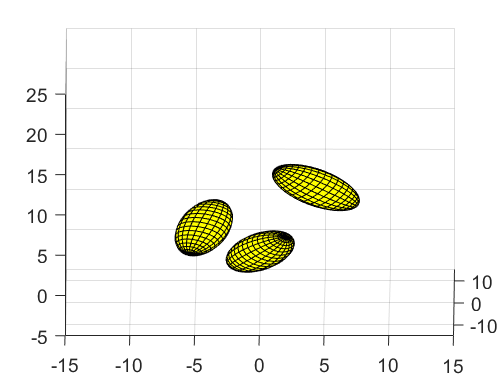

grid on
hold off

t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);

Rx = makehgtform('xrotate',pi/4);
Ry = makehgtform('yrotate',pi/6);
Rz = makehgtform('zrotate',2*pi/3);

Tz = makehgtform('translate',[0 0 5]);
Ty = makehgtform('translate',[0 5 0]);

set(h,'Parent',t1)

h2 = copyobj(h,t2);
h3 = copyobj(h,t3);

set(t1,'Matrix',Ty*Rx*Ry/Ty)
set(t2,'Matrix',Rz*Tz*Ty*Rx*Ry/Ty)
set(t3,'Matrix',(Rz*Tz)^2*Ty*Rx*Ry/Ty)

drawnow

